# Analysing visual coding electrophysiology data from the Allen Brain Observatory, with the Brain Observatory Toolbox

The Allen Brain Observatory resource [1] comprises datasets of neural activity obtained from the mouse visual cortex collected during visual stimulus presentation. The Visual Coding Neuropixels dataset [[2](https://portal.brain-map.org/explore/circuits/visual-coding-neuropixels)] consists of neural activity recordings obtained using multi-channel electrophysiology.

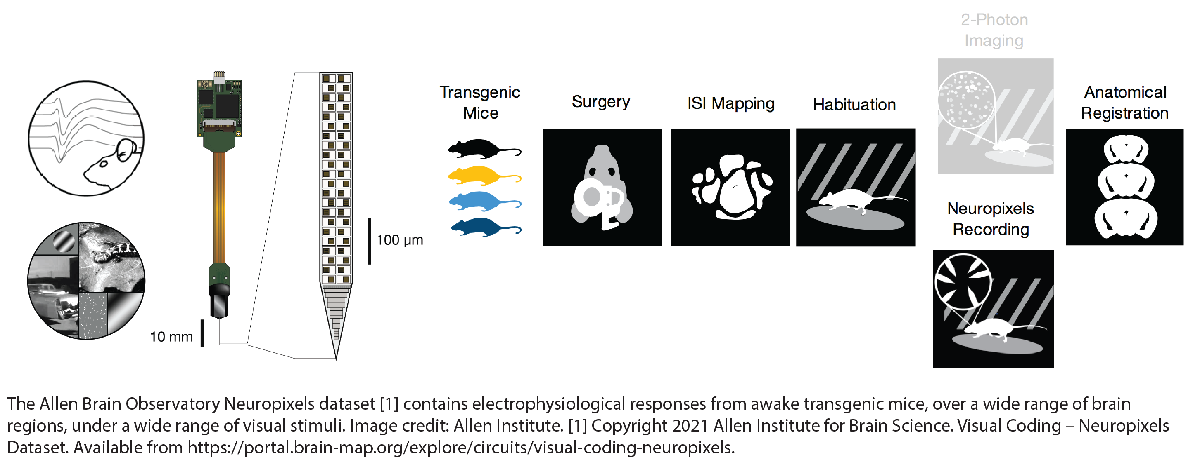

This example demonstrates how to access, search, and filter data from the Visual Coding Neuropixels dataset using the [Brain Observatory Toolbox](https://github.com/emeyers/Brain-Observatory-Toolbox) (BOT). It also shows how to perform some simple analyses of visual responses by neurons in mouse primary visual cortex. Neural response properties such as receptive field and orientation tuning are quantified, along with basic behavioural analysis.

The electrophysiology data for individual experimental sessions can be large — in the order of several GBytes for each experimental session. Be aware that running this demo will cause the download of approximately 5GB of data, which may take considerable time. This data will be cached by the toolbox, so that subsequent runs of the demo will be fast.

## About the Brain Observatory Toolbox (BOT)

The BOT is a MATLAB toolbox for accessing, manipulating and analysing neurophysiology data from the Allen Brain Observatory. The BOT provides convenient methods for identifying data sets of interest, and manages downloading and caching of data from the Allen Brain Observatory.

## The Neuropixels data

The Neuropixels dataset contains extracellular electrophysiology data obtained using high-denisty Neuropixels probes placed in different regions of the mouse brain (for a complete listing see the technical white paper on the Allen Institute's Mouse Common Coordinate Framework [[3](http://help.brain-map.org/download/attachments/2818171/Mouse_Common_Coordinate_Framework.pdf?version=4&modificationDate=1508448259091&api=v2)]). Neural activity from cortex and thalamus was recorded during passive visual stimulation. Further details regarding stimuli can be found in the Allen Institute's technical white paper [[4](https://allensdk.readthedocs.io/en/latest/visual_coding_neuropixels.html#visual-stimulus-sets)]. 

The data was pre-processed using [standard procedures](https://allensdk.readthedocs.io/en/latest/visual_coding_neuropixels.html#data-processing) and saved using [Neurodata Without Borders (NWB)](https://www.nwb.org/) file formats. Neural activity from each channel was saved in two streams 

- A high pass (analog 500 Hz and digital 150 Hz) filtered 'spike band' digitized at 30 kHz (Spikes were sorted using the MATLAB package Kilosort2 and quality metrics computed)

- A low pass (analog 1kHz and digital 625 Hz) filterted 'LFP band' digitized at 2.5 kHz and re-referenced for common noise rejection.

The data is described by several tables containing metadata whereas the actual data is stored in NWB files. Running this demo requires a total of 5GB of data to be downloaded which might take some time the first time. However, the data is then cached by this toolbox making subsequent runs faster. Metadata stored in tables is used to pre-select the data required for an analyses following which, only the minimum required actual data from NWB files is accessed. 

## Obtaining and examining experimental data 

The Neuropixels data is grouped and organized by several ***linked dataset items*** of different types - experimental `sessions`, containing data from several `probes` which, in turn, contain data from multiple `channels` and `units`. Each dataset item type can be accessed using the `bot.fetch``LinkedDatasetItemType``()` functions. Information regarding all dataset items of a particular type with item parameters such as unique identifiers (`id`) are available as tables. An individual dataset item can be queried from the table (using the row) or as an object (using the item id). Objects come with properties used to inspect information related to that particular dataset item or methods for fetching or analyzing data linked to that particular dataset item.

% prepare for demo
prepareForDemo;

We are going to start by accessing all the sessions in this dataset using the `bot.fetchSessions ('ephys')` factory function. To access probes, channels or units instead of sessions, use `bot.fetchProbes`, `bot.fetchChannels` and `bot.fetchUnits` respectively

% - Obtain sessions, probes, channels and units tables
sessions = bot.fetchSessions('ephys'); % for accessing probes, channels, session

Session information is returned as a table. Columns correspond to session parameters

% - Display the sessions manifest
head(sessions)

ans = 8×15 table
       id        unit_count    channel_count    probe_count        session_type         age_in_days    fail_eye_tracking    sex                      full_genotype                                                                      ephys_structure_acronyms                                                    isi_experiment_id    date_of_acquisition     specimen_id      specimen      well_known_files
    _________    __________    _____________    ___________    _____________________    ___________    _________________    ___    _________________________________________________

You can use these tables to locate sessions or individual recordings that meet your criteria, for example, those using wild type animals that included eye tracking data.

% - Select sessions that include valid eye tracking data
sessions = sessions(~sessions.fail_eye_tracking, :);

% - Select sessions on wild-type animals
sessions = sessions(sessions.full_genotype == "wt/wt", :)

sessions = 26×15 table
       id        unit_count    channel_count    probe_count         session_type          age_in_days    fail_eye_tracking    sex    full_genotype                                                      ephys_structure_acronyms                                                      isi_experiment_id    date_of_acquisition     specimen_id      specimen      well_known_files
    _________    __________    _____________    ___________    _______________________    ___________    _________________    ___    _____________    ________________________________________

## Obtaining and examining a single experimental session

The first of the remaining experimental sessions in the `sessions` table can now be examined in more detail. In the BOT, all experimental data are represented by summaries, with loading of large data files (slow) performed only when necessary.

The `bot.session()` function obtains an item object for a single experimental session

% - Obtain a single experimental session
sess = bot.session(sessions(1, :))

sess =   ephyssession with properties:

                              info: [1×1 struct]
                                id: 742951821
                       linkedFiles: [2×1 table]

   Info Derived Values
                structure_acronyms: ["VIS"    "VISal"    "VISl"    "VISp"    "VISpm"    "VISrl"    "grey"]

   Linked Items
                            probes: [6×23 table]
                          channels: [2219×29 table]
                             units: [893×51 table]

   Linked Item Derived Values
       channel_structure_intervals: [18×2 table]
         structurewise_unit_counts: [7×2 table]

   Linked File Values ('SessNWB')
      inter_presentation_intervals: '[on demand]'
                     invalid_times: '[on demand]'
                    mean_waveforms: '[on demand]'
    optogenetic_stimulation_epochs: '[on demand]'
                        pupil_data: '[on demand]'
               pupil_data_

The `session` object collects a number of useful properties for inspection. These include 

- High level information (`.info)` `.linkedFiles` point to the NWB data file 

- More detailed information (`Item Info Values`)

- Tables summarizing the linked dataset items (`Linked Items`) 

- Metrics computed from the linked dataset items (`Linked Item Values`), and 

- Data related properties in `Linked File Values` (`SessNWB and StimTemplatesGroup`). 

Accessing one of the `NWB info` properties will cause data to be loaded from the cache, or downloaded if necessary. Many of these data files can be several GB in size and downloading them for the first time might be slow.

### Querying important information regarding a particular session

Calling the `.info` property obtains some high level information for this session

sess.info

ans = struct with fields:
                          id: 742951821
                  unit_count: 893
               channel_count: 2219
                 probe_count: 6
                session_type: brain_observatory_1.1
                 age_in_days: 120
           fail_eye_tracking: 0
                         sex: M
               full_genotype: "wt/wt"
    ephys_structure_acronyms: "VIS; VISal; VISl; VISp; VISpm; VISrl; grey"
           isi_experiment_id: 732238627
         date_of_acquisition: 26-Oct-2018 19:47:04
                 specimen_id: 723627604
                    specimen: [1×1 struct]
            well_known_files: [1×1 struct]


The `linked items` group of properties accesses linked probes, channels and units

"This recording had " + sess.info.probe_count + " probes, " + sess.info.channel_count + " channels and " + sess.info.unit_count + " units"

ans = "This recording had 6 probes, 2219 channels and 893 units"

The `linked item values` property group retrieves metrics associated with `linked items`

For example, `.structurewise_unit_counts` lists the brain regions from which the units in this session were recorded

sess.structurewise_unit_counts

ans = 7×2 table
    ephys_structure_acronym    count
    _______________________    _____

             grey               554 
             VIS                108 
             VISrl               79 
             VISl                52 
             VISal               44 
             VISp                33 
             VISpm               23 


## Accessing data linked to a particular experimental session

After obtaining high level information, linked items and associated data can be queried

### Accessing linked items : firing rates across brain regions

Linked items properties provide access to the probes, channels and units in this session.

For example, units can be accessed to compute their firing rates across the different brain regions stored in `.info.ephys_structure_acronyms`

% get brain regions recorded
brainRegionsRecorded = sess.info.ephys_structure_acronyms;
brainRegionsRecorded = strip(split(brainRegionsRecorded,';'));
% filter units by brain regions
units = sess.units;
UnitsByBrainRegion = cellfun(@(x)(units(units.ephys_structure_acronym==x,:)),brainRegionsRecorded,...
'UniformOutput',0);
% get firing rates of all units by brain region
firingRatesByBrainRegion = cellfun(@(x)(x.firing_rate),UnitsByBrainRegion,'UniformOutput',0); 

Separating cortical (those beginning with VIS) from subcortical areas

% separate cortical (VIS) and subcortical areas
corticalIndices = contains(brainRegionsRecorded,'VIS');
corticalFiringRates = cell2mat(firingRatesByBrainRegion(corticalIndices));
subCorticalFiringRates = cell2mat(firingRatesByBrainRegion(~corticalIndices));

...and plotting firing rates of cortical and sub-cortical regions along with some central statistics (medians)

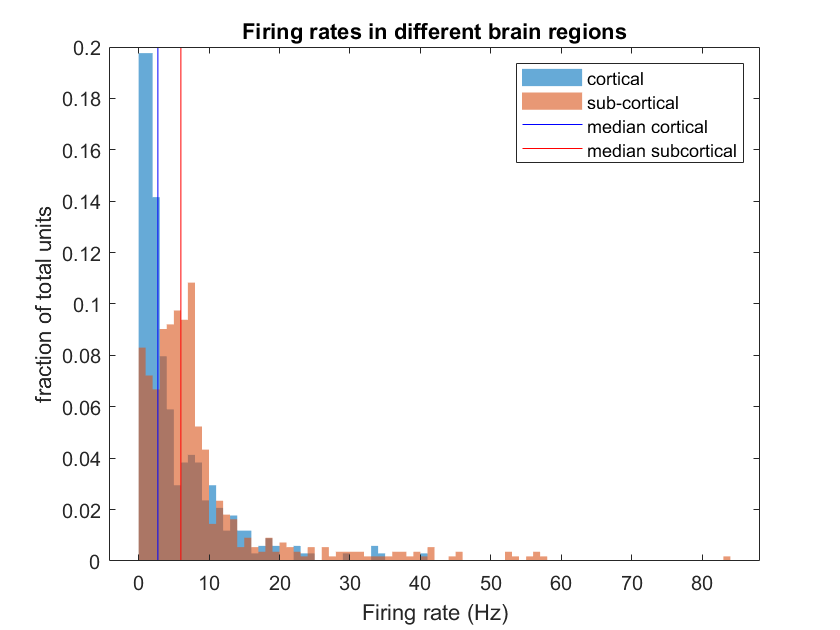

% plot histogram
histogram(corticalFiringRates,'Normalization','probability','BinWidth',1,'EdgeColor','none');hold on
histogram(subCorticalFiringRates,'Normalization','probability','BinWidth',1,'EdgeColor',"none"); hold off
% add statistics
line([median(corticalFiringRates) median(corticalFiringRates)],get(gca,'YLim'),'Color','b')
line([median(subCorticalFiringRates) median(subCorticalFiringRates)],get(gca,'YLim'),'Color','r')
legend({'cortical','sub-cortical','median cortical','median subcortical'})
title('Firing rates in different brain regions')
xlabel('Firing rate (Hz)')
ylabel('fraction of total units')

In this case, the visual cortex had lower firing rates than those observed from the sub-cortical regions (in this session, subcortical grey matter)

### Accessing Linked File Values : visualizing pupil location 

Actual data can be retrieved using the linked file values and might be slow for the first run.

Here, `.pupil_data`  retrieves pupil tracking data to visualise the pupil location as a location density map.

% Get the table of pupil locations
pupil_loc = sess.pupil_data

pupil_loc = 288131×16 table
    timestamps    corneal_reflection_center_x    corneal_reflection_center_y    corneal_reflection_height    corneal_reflection_width    corneal_reflection_phi    pupil_center_x    pupil_center_y    pupil_height    pupil_width    pupil_phi    eye_center_x    eye_center_y    eye_height    eye_width    eye_phi 
    __________    ___________________________    ___________________________    _________________________    ________________________    ______________________    ______________    ______________    ____________    ___________</

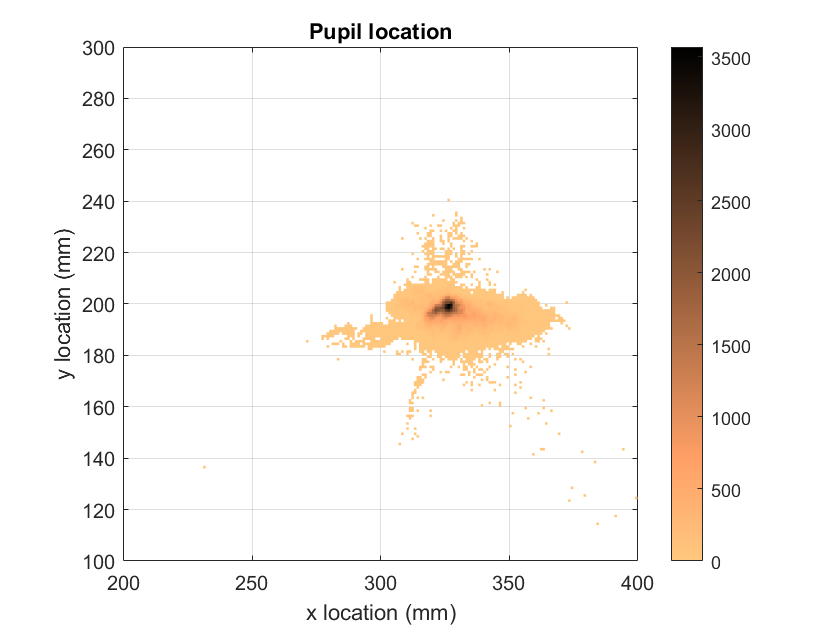

% Plot a 2D histogram of pupil location
histogram2(pupil_loc.pupil_center_x, pupil_loc.pupil_center_y, 'DisplayStyle', 'tile');
xlim([200 400]);
ylim([100 300]);
cmap = copper();
colormap(cmap(end:-1:1, :));
axis square;
xlabel('x location (mm)');
ylabel('y location (mm)');
title('Pupil location');
colorbar

### Examining the stimuli used in this experiment

The properties `.stimulus_names`, `.stimulus_conditions`, `.stimulus_presentations` etc. contain information about what stimuli were presented in this session, and details about the stimulus parameters and in what order the stimuli were presented.

% Show which stimuli were presented in this session
sess.stimulus_names

ans = 8×1 string array
    "drifting_gratings"
    "flashes"
    "gabors"
    "natural_movie_one"
    "natural_movie_three"
    "natural_scenes"
    "spontaneous"
    "static_gratings"


% Get a table with detailed parameters for each stimulus
head(sess.stimulus_conditions)

ans = 8×17 table
    contrast      mask       opacity    orientation                 phase                       size         spatial_frequency    stimulus_name    temporal_frequency      units      stimulus_block_condition_id    frame    x_position    y_position      color_triplet      color    stimulus_condition_id
    ________    _________    _______    ___________    ________________________________    ______________    _________________    _____________    __________________    _________    ___________________________

% Get a full table of inidividual stimulus presentations
stimuli = sess.stimulus_presentations;
head(stimuli)

ans = 8×19 table
    contrast    stimulus_block_id    orientation                 phase                       size         spatial_frequency    start_time    stimulus_block    stimulus_name    stop_time    temporal_frequency    stimulus_block_condition_id    frame    x_position    y_position    stimulus_presentation_id    color    duration    stimulus_condition_id
    ________    _________________    ___________    ________________________________    ______________    _________________    __________    ______________    _______

### Stimulus conditions and stimulus presentations

The stimuli in a session are identified using two different properties

- `stimulus_conditions - `identical stimuli grouped by condition

- `stimulus_presentations - `each individual presentation

For example, all the stimuli with a `stimulus_condition_id` of 1 have different `stimulus_presentation_ids.` 

The stimulus properties for each stimulus condition can be inferred from the other columns of the table.

stimuli(stimuli.stimulus_condition_id==1,:)

ans = 15×19 table
    contrast    stimulus_block_id    orientation                 phase                       size         spatial_frequency    start_time    stimulus_block    stimulus_name    stop_time    temporal_frequency    stimulus_block_condition_id    frame    x_position    y_position    stimulus_presentation_id    color    duration    stimulus_condition_id
    ________    _________________    ___________    ________________________________    ______________    _________________    __________    ______________    ______

The method .`conditionwise_spike_statistics()` computes spike statistics by stimulus condition whereas the method .`presentationwise_spike_counts()` returns spike counts for different stimulus presentations.

### Examining details of an individual stimulus presentation (Gabor patches)

One of the stimuli used were Gabor patches of different orientations that were distributed across the visual field in a grid like manner. 

% extract Gabor patches from stimulus set
StimIndices = stimuli(stimuli.stimulus_name=='gabors', :);
% extract stimulus locations and orientations
StimXloc = unique(StimIndices.x_position);
StimYloc = unique(StimIndices.y_position);
StimOrnt = unique(StimIndices.orientation);
% display stimulus properties
['stimulus x pos: ',num2str(StimXloc'),newline,...
    'stimulus y pos: ',num2str(StimYloc'),newline,...
    'stimulus orientation: ',num2str(StimOrnt')]

ans =     'stimulus x pos: -40 -30 -20 -10   0  10  20  30  40
     stimulus y pos: -40 -30 -20 -10   0  10  20  30  40
     stimulus orientation: 0  45  90'


## Examining data from a single unit

Linked items can be accessed via the `.<LinkedItems>` property. For example, .units retrieves all the units in this session. Units from a specific area, such as primary visual cortex (`'VISp'`) can bow be filtered out. 

A `units` table row, or `unit_id` of interest is used to pick a unit to construct a unit object using the `bot.unit()` function

units = sess.units;
units = units(units.ephys_structure_acronym == 'VISp', :)

units = 33×51 table
       id        ephys_channel_id    ephys_probe_id    ephys_session_id        session_type         ephys_structure_acronym     L_ratio      age_in_days    air_channel_index    amplitude_cutoff    anterior_posterior_ccf_coordinate    cumulative_drift    d_prime    dorsal_ventral_ccf_coordinate    fail_eye_tracking    firing_rate    has_lfp_data    isi_violations    isolation_distance    left_right_ccf_coordinate    lfp_temporal_subsampling_factor    max_drift    nn_hit_rate    nn_miss_rate    peak_channel    presence_ratio    

% Obtain a `unit` object for the first unit
unit = bot.unit(units(1, :)) %#ok<NASGU>

unit =   ephysunit with properties:

       info: [1×1 struct]
         id: 950946855

   Linked Items
    session: [1×1 bot.item.ephyssession]
    channel: [1×1 bot.item.ephyschannel]
      probe: [1×1 bot.item.ephysprobe]


% or alternatively:
unit = bot.unit(units{1, 'id'})

unit =   ephysunit with properties:

       info: [1×1 struct]
         id: 950946855

   Linked Items
    session: [1×1 bot.item.ephyssession]
    channel: [1×1 bot.item.ephyschannel]
      probe: [1×1 bot.item.ephysprobe]


The `unit` object holds references to the `session`, `probe` and `channel` that it belongs to, as well as information about this unit:

fieldnames (unit.info)

ans = 51×1 cell array
    {'id'                               }
    {'ephys_channel_id'                 }
    {'ephys_probe_id'                   }
    {'ephys_session_id'                 }
    {'session_type'                     }
    {'ephys_structure_acronym'          }
    {'L_ratio'                          }
    {'age_in_days'                      }
    {'air_channel_index'                }
    {'amplitude_cutoff'                 }
    {'anterior_posterior_ccf_coordinate'}
    {'cumulative_drift'                 }
    {'d_prime'                          }
    {'dorsal_ventral_ccf_coordinate'    }
    {'fail_eye_tracking'                }
    {'firing_rate'                      }
    {'has_lfp_data'                     }
    {'isi_violations'                   }
    {'isolation_distance'               }
    {'left_right_ccf_coordinate'        }
    {'lfp_temporal_subsampling_factor'  }
    {'max_drift'                        }
    {'nn_hit_rate'                      }
    {'nn_mis

### Examine stimulus-related responses for this unit

The stimulus related responses for this particular unit can now be queried. First, the responses of this unit to the different Gabor patches are displayed to determine its receptive field.

#### Determine the receptive field for this unit

The stimulus IDs for the Gabor patches (`GaborPatchIndices.stimulus_presentation_id`) will be used to extract spike counts for each spatial presentation of the Gabor patch using the `getConditionwiseSpikeStatistics()` method. 

The `getConditionwiseSpikeStatistics()` method computes spike statistics on data grouped by stimulus conditions. Since all stimulus conditions were not repeated in all experiments, some of these are invalid for the current unit and will be populated by `NaN` values which are removed.

% extract spk statistics by stimulus conditions and remove invalid conditions
spkCounts = sess.getConditionwiseSpikeStatistics(StimIndices.stimulus_presentation_id,unit.id);
spkCounts = rmmissing(spkCounts);

Looping through the Gabor patches, to plot the spike counts for each stimulus location. The `stimulus_condition_id` helps retrieve the data

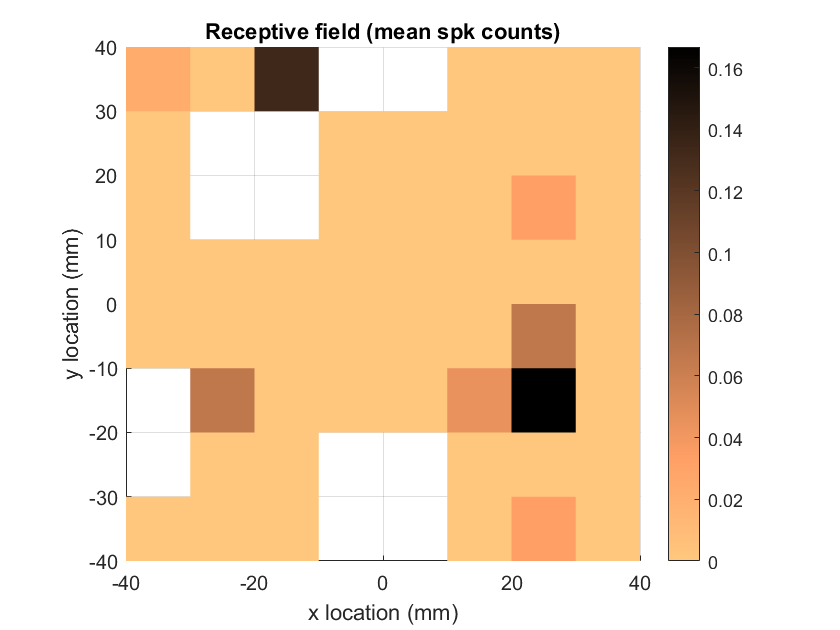

scnt = zeros(length(StimXloc),length(StimYloc));
for ii = 1:length(StimXloc) % loop through stimulus positions
    for jj = 1:length(StimYloc)
        validStimIndices = StimIndices.x_position == StimXloc(ii) & ...
            StimIndices.y_position == StimYloc(jj);
        StimConditionIds = unique(StimIndices.stimulus_condition_id(validStimIndices)); % matching stim conditions
        ValidConditionIds = ismember(spkCounts.stimulus_condition_id,StimConditionIds); % find stim conditions valid for unit
        scnt(ii,jj) = sum(spkCounts.spike_count(ValidConditionIds))/...
            sum(spkCounts.stimulus_presentation_count(ValidConditionIds));
    end
end
% plot the data
surf(StimXloc,StimYloc,scnt)
shading flat
axis square
view([0 90])
colorbar
ylabel('y location (mm)')
xlabel('x location (mm)')
title('Receptive field (mean spk counts)')

#### Determine the orientation tuning for this unit

Next, an orientation tuning curve for this unit will be computed using the `"static_gratings"` [stimuli](http://observatory.brain-map.org/visualcoding/stimulus/static_gratings#:~:text=The%20static%20grating%20stimulus%20consists,the%20position%20of%20the%20grating).&text=At%20the%20intersections%20of%20these,corresponding%20to%20a%20different%20phase.). 

% Identify static grating stimuli
stimuli = sess.stimulus_presentations;
staticGratingIndices = stimuli(stimuli.stimulus_name == "static_gratings", :);
stimulusPresentationIds = staticGratingIndices.stimulus_presentation_id;

The `getPresentationwiseSpikeCounts()` method measures the unit responses to these stimuli. A peri-stimulus time histogram (PSTH) of several unit responses from the same probe, helps choose a selective time window for the response. 

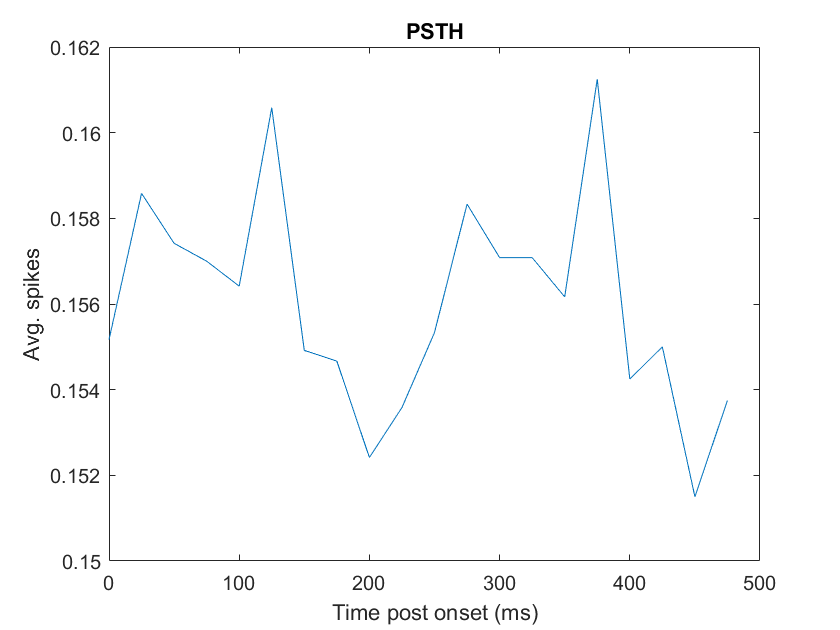

% Build a PSTH (enter the number of trials to use for PSTH calculation,
% more trials will require longer computational time)
nPsthUnits = str2double("2"); % please enter a number between 2 and 20
timeBins = 0:25e-3:500e-3;
psth = sess.getPresentationwiseSpikeCounts(timeBins, stimulusPresentationIds, unit.probe.units{1:nPsthUnits, 'id'});
% Plot the PSTH
plot(timeBins(1:end-1) * 1e3, mean(psth, [2 3]));
xlabel('Time post onset (ms)');
ylabel('Avg. spikes');
title('PSTH');

The same BOT method `getPresentationwiseSpikeCounts()` extracts the responses to all oriented grating stimuli. 

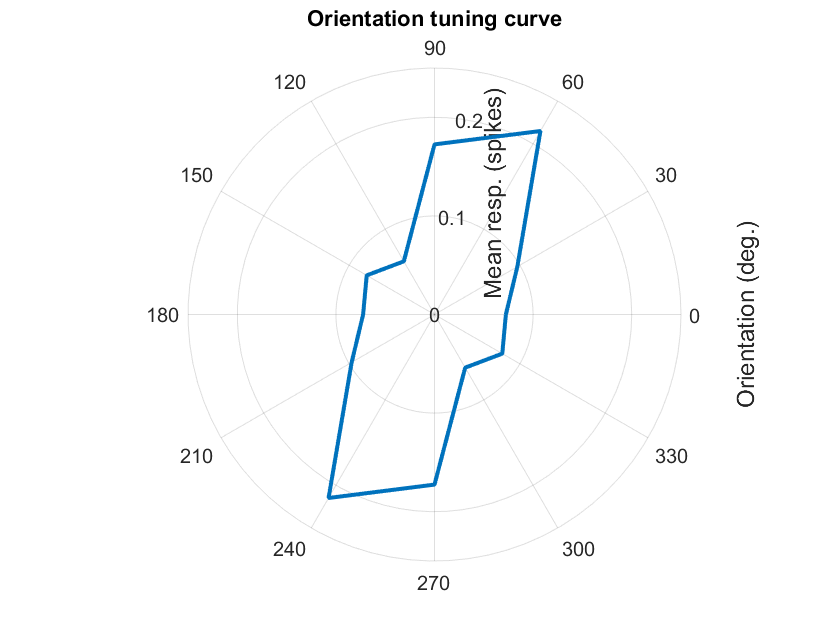

% Compute stimulus responses after selecting response window
respWindow = [250 500] * 1e-3;
responses = sess.getPresentationwiseSpikeCounts(respWindow, stimulusPresentationIds, unit.id);
% Collect stimuli by stimulus orientation
stimOrientation = staticGratingIndices.orientation;
[condOrientation, ~, oriIndex] = unique(stimOrientation);
blanks = isnan(stimOrientation);
oriIndex(blanks) = 7;
% Calculate mean and std. dev. of responses per stimulus orientation
respMean = accumarray(oriIndex, responses, [], @mean);
respStd = accumarray(oriIndex, double(responses), [], @std);
% Plot an orientation tuning curve
orientation = deg2rad(condOrientation);
orientation = [orientation(1:6); orientation(1:6) + pi; orientation(1)];
polarplot(orientation, respMean([1:6 1:6 1]), 'LineWidth', 2);
a = gca;
a.RAxis.Label.String = 'Mean resp. (spikes)';
a.ThetaAxis.Label.String = 'Orientation (deg.)';
title('Orientation tuning curve')

This unit from primary visual cortex was tuned to the orientation of a visual stimulus.

## Accessing probe-centric data

In addition to high frequency data capturing spikes, low frequency data capturing slow oscillations were also recorded from individual probes. 

Current-source density (CSD) and local-field potential (LFP) measurements access low frequency data and are accessed using methods from `probe` objects.

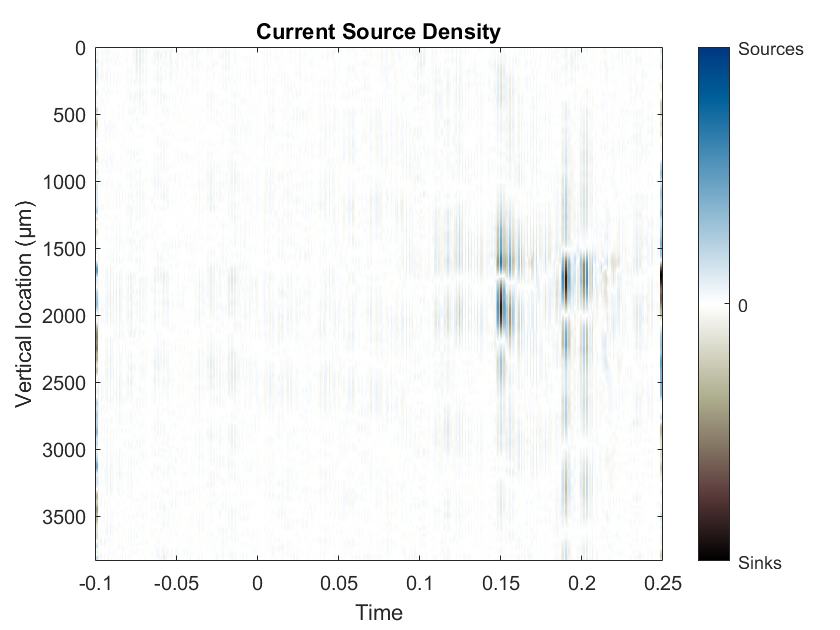

% Get the probe object for this unit
probe = unit.probe;

% Extract CSD data for this probe
tt = probe.csdData.data; % timetable 
vposns = probe.csdData.verticalPositions;

% Plot the CSD data
figure, imagesc(seconds(tt.Time), vposns, table2array(tt));
colormap(vertcat(flipud(1-bone()), 1-copper()));
max_amp = max(abs(caxis));
colorbar('Ticks',[-max_amp,0,max_amp],'Ticklabels',{'Sinks','0','Sources'})
caxis([-1 1] * max_amp);
xlabel('Time');
ylabel('Vertical location (µm)');
title('Current Source Density');

## Utility functions

function prepareForDemo
clearvars
warning('off')
clc
end

## References

[1] Copyright 2016 Allen Institute for Brain Science. Allen Brain Observatory. Available from: [portal.brain-map.org/explore/circuits](http://portal.brain-map.org/explore/circuits). 

[2] Copyright 2019 Allen Institute for Brain Science. Visual Coding Neuropixels. Available from: [portal.brain-map.org/explore/circuits/visual-coding-neuropixels](https://portal.brain-map.org/explore/circuits/visual-coding-neuropixels).

[3] Copyright 2017 Allen Institute for Brain Science. Technical White Paper on the Mouse Common Coordinate Framework. Available from: [http://help.brain-map.org/download/attachments/2818171/Mouse_Common_Coordinate_Framework.pdf?version=4&modificationDate=1508448259091&api=v2](http://help.brain-map.org/download/attachments/2818171/Mouse_Common_Coordinate_Framework.pdf?version=4&modificationDate=1508448259091&api=v2).

[4] Copyright 2019 Allen Institute for Brain Science. Technical White Paper on the Visual Coding Neuropixels dataset. Available from: [https://brainmapportal-live-4cc80a57cd6e400d854-f7fdcae.divio-media.net/filer_public/80/75/8075a100-ca64-429a-b39a-569121b612b2/neuropixels_visual_coding_-_white_paper_v10.pdf](https://brainmapportal-live-4cc80a57cd6e400d854-f7fdcae.divio-media.net/filer_public/80/75/8075a100-ca64-429a-b39a-569121b612b2/neuropixels_visual_coding_-_white_paper_v10.pdf).